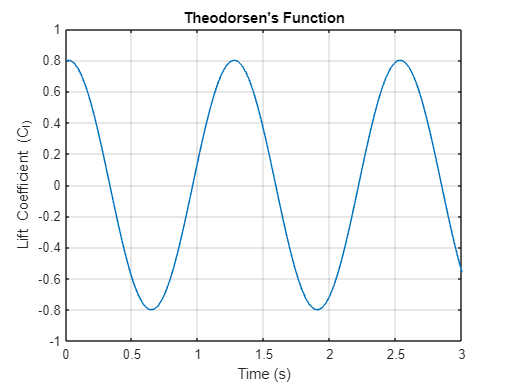

% Parameters
omega = 5; % Circular frequency (rad/s)
b = 0.5;   % Semi-chord length (ft)
v_inf = 25; % Freestream velocity (ft/s)
alpha_bar = 8 * pi / 180; % Amplitude of oscillation (rad)

% Compute Theodorsen's function
k = omega * b / (2 * v_inf);
C = besselh(1, 2, k) ./ (besselh(1, 2, k) + 1i * besselh(0, 2, k));

% Time vector
t = linspace(0, 3, 100); % Approximately 2 periods

% Compute lift coefficient
Cl = 2 * pi * (C + 1i * omega * b / (2 * v_inf)) * alpha_bar * exp(1i * omega * t);

% Plot real part of Cl
figure;
plot(t, real(Cl));
xlabel('Time (s)');
ylabel('Lift Coefficient (C_l)');
title('Theodorsen''s Function');
grid on;